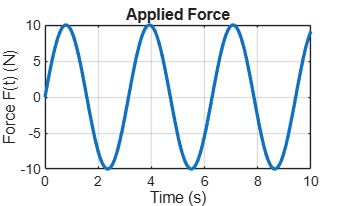

clc;        % Clear command window
clear;      % Remove all variables from workspace
close all;  % Close all open figures

%% System Parameters

m = 5;      % Mass (kg)
c = 1;      % Damping coefficient (N.s/m)
k = 8;     % Spring stiffness (N/m)

%% Time Vector


t = linspace(0,10,500)';  
% Generate 500 time points between 0 and 10 seconds
% Column vector is required for easier calculations

%% External Force

F = 10*sin(2*t);
% Define applied force:
% F(t) = 10*sin(2t)

%% Convert 2nd Order ODE to 1st Order System

odefun = @(t,y) [ ...
    y(2);                                              % dx/dt = velocity
    (10*sin(2*t) - c*y(2) - k*y(1))/m ];              % d²x/dt² from governing equation

% Original equation:
% m*x'' + c*x' + k*x = 10*sin(2*t)
%
% Define:
% y(1) = x      (displacement)
% y(2) = x'     (velocity)
%
% Then:
% y1' = y2
% y2' = (F - c*y2 - k*y1)/m

%% Initial Conditions

x0 = 0;      % Initial displacement x(0)
v0 = 0;      % Initial velocity x'(0)

%% Solve Differential Equation

[tSol,ySol] = ode45(odefun,t,[x0 v0]);

% ode45 numerically solves the ODE
%
% Inputs:
% odefun    -> Differential equation
% t         -> Time span
% [x0 v0]   -> Initial conditions
%
% Outputs:
% tSol      -> Time points
% ySol      -> Solution matrix

%% Extract Displacement

x = ySol(:,1);

% Column 1 = displacement x(t)
% Column 2 = velocity x'(t)

%% Plot Applied Force

figure
plot(t,F,'LineWidth',2)
xlabel('Time (s)')
ylabel('Force F(t) (N)')
title('Applied Force')
grid on

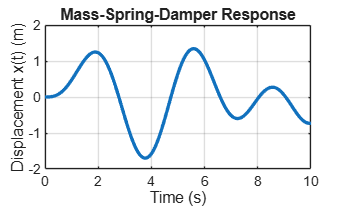


%% Plot Displacement Response

figure
plot(tSol,x,'LineWidth',2)
xlabel('Time (s)')
ylabel('Displacement x(t) (m)')
title('Mass-Spring-Damper Response')
grid on


%% Display First Few Values

disp(table(tSol(1:10),F(1:10),x(1:10), ...
    'VariableNames',{'Time','Force','Displacement'}))

     Time       Force     Displacement
    _______    _______    ____________

          0          0              0 
    0.02004    0.40069     5.3595e-06 
    0.04008    0.80075     4.2791e-05 
    0.06012     1.1995     0.00014424 
    0.08016     1.5963     0.00034138 
     0.1002     1.9906     0.00066546 
    0.12024     2.3817      0.0011473 
    0.14028     2.7689      0.0018174 
    0.16032     3.1518      0.0027055 
    0.18036     3.5295       0.003841 




% Prints:
% Time    Force    Displacement
%
% Useful for creating PINN training data